# 1. mesh generation

% Mesh generation for a unit square domain
numNodesX = 20;
numNodesY = 20;
Lx = 1;
Ly = 1;

% Create grid of points
[x, y] = meshgrid(linspace(0, Lx, numNodesX), linspace(0, Ly, numNodesY));
x = x(:);
y = y(:);

% Create connectivity for triangular elements
tri = delaunay(x, y);

numNodes = length(x);
numElements = size(tri, 1);


# 2. Assembly of Stiffness Matrix and Load Vector

% Initialize the global stiffness matrix and load vector
K = sparse(numNodes, numNodes);
F = zeros(numNodes, 1);

% Integration points and weights for a 3-point Gaussian quadrature
gaussPoints = [1/6 1/6; 2/3 1/6; 1/6 2/3];
gaussWeights = [1/6 1/6 1/6];

% Loop over elements to assemble the global stiffness matrix and load vector
for e = 1:numElements
    nodes = tri(e, :);
    xe = x(nodes);
    ye = y(nodes);
    
    % Compute the element stiffness matrix and load vector
    Ke = zeros(3, 3);
    Fe = zeros(3, 1);
    
    % Area of the triangle
    Ae = polyarea(xe, ye);
    
    % Compute local stiffness matrix and load vector
    for gp = 1:length(gaussWeights)
        N = [gaussPoints(gp, 1) gaussPoints(gp, 2) 1-gaussPoints(gp, 1)-gaussPoints(gp, 2)];
        dN_dxi = [-1 1 0; -1 0 1];
        
        % Jacobian matrix
        J = [xe ye]' * dN_dxi';
        detJ = det(J);
        invJ = inv(J);
        
        % Gradient of shape functions
        dN_dxy = invJ' * dN_dxi;
        
        % Stiffness matrix contribution
        Ke = Ke + dN_dxy' * dN_dxy * detJ * gaussWeights(gp) * Ae;
        
        % Load vector contribution
        xgp = N * xe;
        ygp = N * ye;
        fgp = sin(pi * xgp) * sin(pi * ygp);
        Fe = Fe + N' * fgp * detJ * gaussWeights(gp) * Ae;
    end
    
    % Assemble into global matrices
    K(nodes, nodes) = K(nodes, nodes) + Ke;
    F(nodes) = F(nodes) + Fe;
end

# 3. Applying Boundary Conditions

% Find boundary nodes
tol = 1e-6;
boundaryNodes = find(abs(x) < tol | abs(y) < tol | abs(x - Lx) < tol | abs(y - Ly) < tol);

% Apply Dirichlet boundary conditions
for i = 1:length(boundaryNodes)
    node = boundaryNodes(i);
    K(node, :) = 0;
    K(node, node) = 1;
    F(node) = 0;
end

# 4. Solving the Linear System

% Solve the linear system
U = K \ F;

# 5. Post-processing (Visualization)

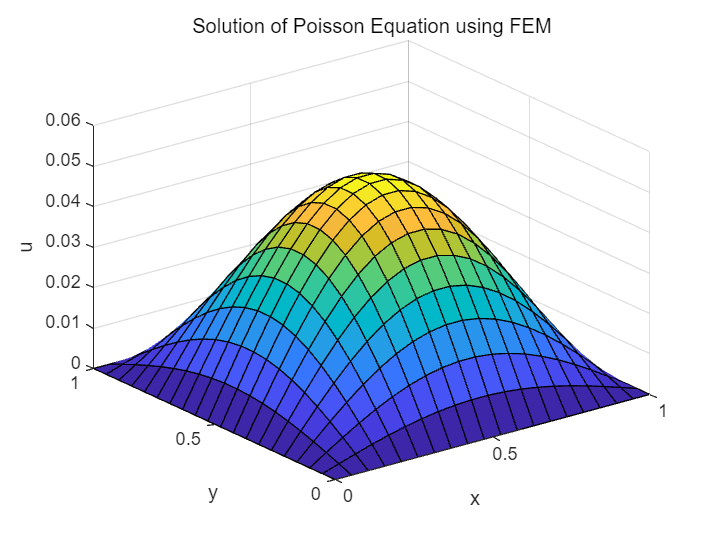

% Reshape solution for visualization
U_reshaped = reshape(U, numNodesY, numNodesX);

% Plot the solution
figure;
surf(linspace(0, Lx, numNodesX), linspace(0, Ly, numNodesY), U_reshaped);
title('Solution of Poisson Equation using FEM');
xlabel('x');
ylabel('y');
zlabel('u');